# DC motor system Identification

First step is loading the input/output data

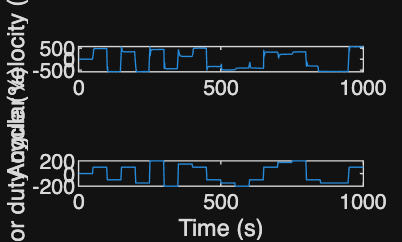

load('/Users/jairoviola/Documents/MATLAB/DT_COSMOS/DCMotorIO.mat')

PWM=BMInput(:,2);
temp=BMOut(:,2);
ts=BMInput(2,1);

sysDataIdent=iddata(temp,PWM,ts);

figure()
subplot(2,1,1)
plot(temp)
ylabel('Angular velocity (RPM)')
subplot(2,1,2)
plot(PWM)
ylabel('Motor duty cycle (%)')
xlabel('Time (s)')

Second step is estimating a first and second-order model with delay using the procest command in matlab

%estimate a first-order system
sysFirst = procest(sysDataIdent,"P1D");
kp = sysFirst.Kp;
sysFirst.Report;

%estimate a second-order system
sysSecond = procest(sysDataIdent,"P2DU");
kp = sysSecond.Kp;
sysSecond.Report;

Plot the identified system step responses

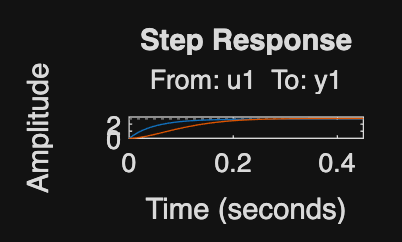

figure()
step(sysFirst,sysSecond)

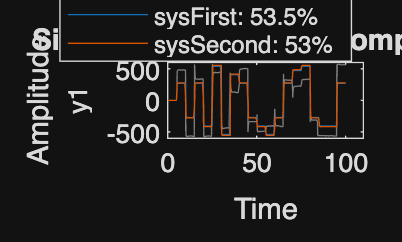

figure()
compare(sysDataIdent,sysFirst,sysSecond)

sysFirst.Report;
sysSecond.Report;